Punto 1

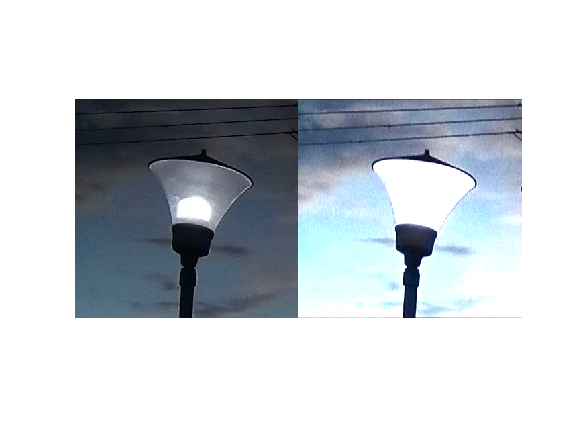

I = imread("img.jpg");

masc = [0 0.5 0; 0 1 0; 0 0.5 0];
masc = uint8(masc);
IR = Filter(I(:,:,1),masc);
IG = Filter(I(:,:,2),masc);
IB = Filter(I(:,:,3),masc);
Im = cat(3,IR,IG,IB);

imshow(cat(2,I,Im))

Punto 2

I = imread("img.jpg");
G = rgb2gray(I);
[imagen,margen] = MargenImagen(G,7);
imagen

imagen = 332×339 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0   30   30   31   32   33   33   32   30   29   34   34   33   30   30   33   33   31   32   34   33   32   34   32   29   31   30   33   33   29   28   31   32   30   28   28   28   29   29   29   28   27   30   25   23   26   31   32   29
    0    0   30   30   31   32   33   33   32   30   29   34   34   33   30   30   33   33   31   32   34   33   32   34   32   29   31   30   33   33   29   28   31   32   30   28   28   28   29   29   29   28   27  

Punto 3

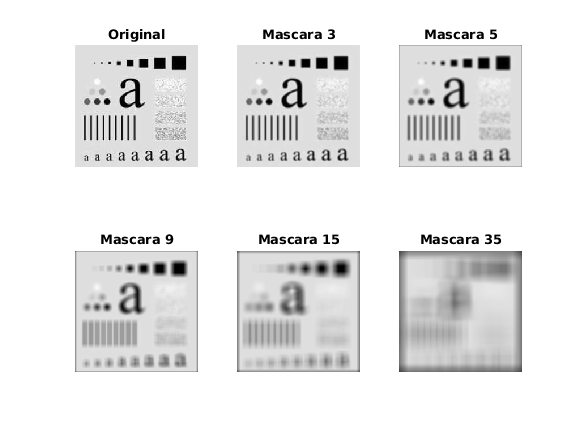

I = imread('a.png');
Gray = rgb2gray(I);
figure
subplot(2,3,1)
imshow(Gray); title("Original");
subplot(2,3,2)
imagen1 = FilterMean(Gray, 3);
imshow(imagen1); title("Mascara 3");
subplot(2,3,3)
imagen2 = FilterMean(Gray, 5);
imshow(imagen2); title("Mascara 5");
subplot(2,3,4)
imagen3 = FilterMean(Gray, 9);
imshow(imagen3); title("Mascara 9");
subplot(2,3,5)
imagen4 = FilterMean(Gray, 15);
imshow(imagen4); title("Mascara 15");
subplot(2,3,6)
imagen5 = FilterMean(Gray, 35);
imshow(imagen5); title("Mascara 35");

Punto 4

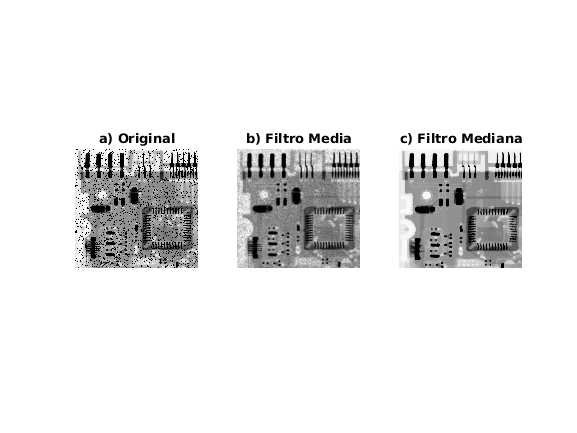

I = imread('circuit.jpg');
figure
subplot(1,3,1)
imshow(I); title("a) Original");
subplot(1,3,2)
imagenMean = FilterMean(I, 5);
imshow(imagenMean); title("b) Filtro Media");
subplot(1,3,3)
imagenMedian = FilterMedian(I, 7);
imshow(imagenMedian); title("c) Filtro Mediana");

Punto 5

A

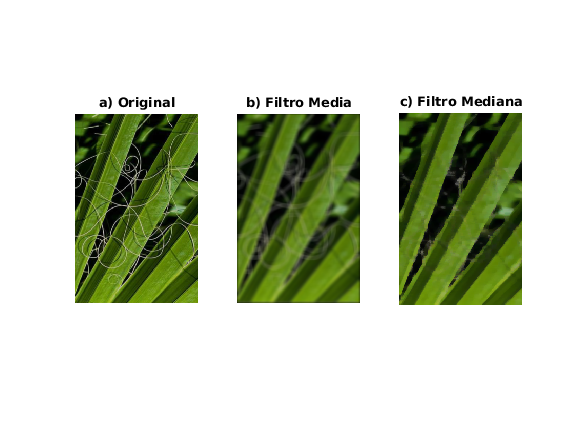

I = imread('green.png');
figure
subplot(1,3,1)
imshow(I); title("a) Original");
subplot(1,3,2)
RM = FilterMean(I(:,:,1), 9);
GM = FilterMean(I(:,:,2), 9);
BM = FilterMean(I(:,:,3), 9);
imshow(cat(3,RM,GM,BM)); title("b) Filtro Media");
subplot(1,3,3)
Rm = FilterMedian(I(:,:,1), 9);
Gm = FilterMedian(I(:,:,2), 9);
Bm = FilterMedian(I(:,:,3), 9);
imshow(cat(3,Rm,Gm,Bm)); title("c) Filtro Mediana");

B

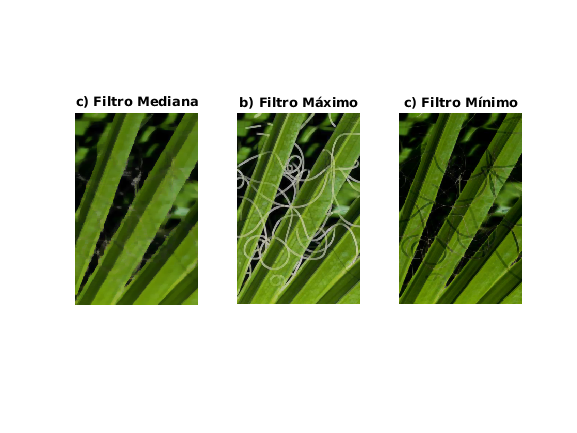

I = imread('green.png');
figure
subplot(1,3,1)
imshow(cat(3,Rm,Gm,Bm)); title("c) Filtro Mediana");
subplot(1,3,2)
RMax = FilterMax(I(:,:,1), 3);
GMax = FilterMax(I(:,:,2), 3);
BMax = FilterMax(I(:,:,3), 3);
imshow(cat(3,RMax,GMax,BMax)); title("b) Filtro Máximo");
subplot(1,3,3)
RMin = FilterMin(I(:,:,1), 3);
GMin = FilterMin(I(:,:,2), 3);
BMin = FilterMin(I(:,:,3), 3);
imshow(cat(3,RMin,GMin,BMin)); title("c) Filtro Mínimo");

Punto 6 

A

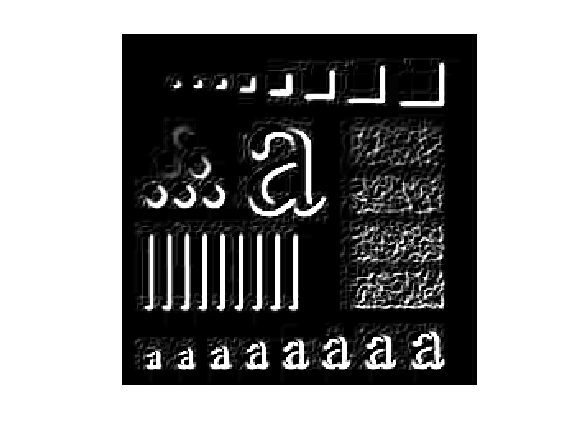

I = imread('a.png');
Gr = rgb2gray(I);
Gr = double(Gr);
F1 = [-1 -2 -1; 0 0 0; 1 2 1];
Gx = Filter(Gr, F1);
F2 = [-1 0 1; -2 0 2; -1 0 1];
Gy = Filter(Gr, F2);
Gx =uint8(Gx);
Gy =uint8(Gy);
G = Gx+Gy;
figure
imshow(G)

B

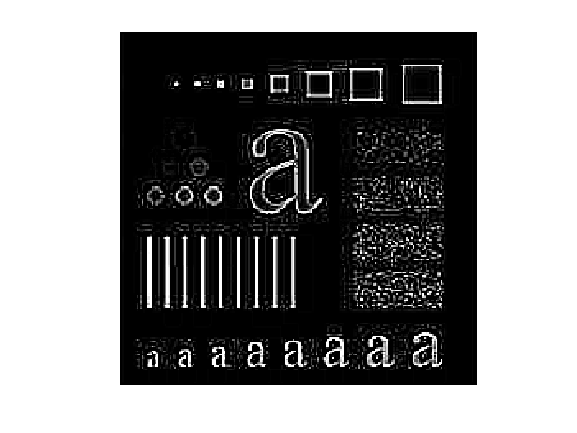

I = imread('a.png');
G = rgb2gray(I);
G = double(G);
F = [1 1 1; 1 -8 1; 1 1 1];
imgFilteres = Filter(G, F);
imgFilteres = uint8(imgFilteres);
figure
imshow(imgFilteres)

punto 7

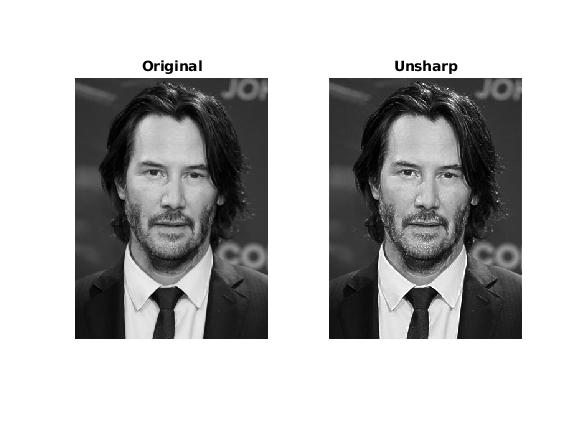

I = imread('Keanu.jpg');
imagen=rgb2gray(I);
figure
subplot(1,2,1)
imshow(imagen); title("Original");
subplot(1,2,2)
Un = UnsharpMask(imagen,9);
imshow(Un); title("Unsharp");